clear; close all

% First we define a line
x = 0:0.01:5;
t = 4;
m = -0.5;

y = m .* x + t;

% add noise to line
rng(1208);

amp = 2;
noise = amp .* (rand(size(y)) - 0.5);

% this are the points where we want to fit our line later
Y = y + noise;
X = x;

figure(1);
hold on; grid on; axis tight;
plot(x, y);
plot(x, Y, '.', 'Color', 'r');


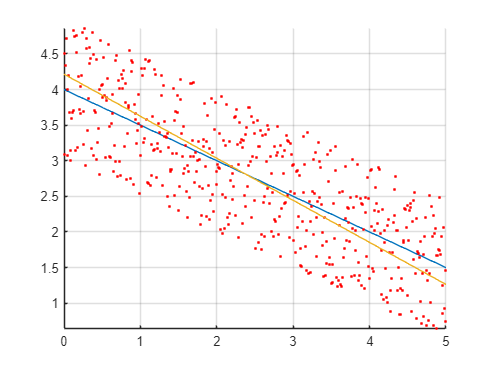

% Standard Line equation is Ax + By + C = 0 and is used as error-function
% for our line fit
% therefore we get a homogeneous system of linear equation of U * Theta = 0

U = [X', Y', ones(numel(Y), 1)];
y = zeros(numel(Y),1);

% trivial solution is:
Theta = U\y;

%% nontrivial solution
% constrain |Theta|^2 = 1 to get a nontrivial solution -- A^2 + B^2 = 1
n = numel(X);

x_bar = (-1/n)*sum(X);
y_bar = (-1/n)*sum(Y);

U = [X'+x_bar, Y'+y_bar];

[V, D] = eig(U.'*U);
[~, idx] = min(diag(D));
Theta = V(:, idx);

A = Theta(1);
B = Theta(2);
C = A * x_bar + B * y_bar;

y_hat =  (-A .* x - C) / B;

figure(1)
hold on;
plot(x, y_hat)


assert((1 - (A^2 + B^2)) <1e-6)






